## **Assignment Question Analysis**

Question 1: Bandwidth Limitation and Rectangular Pulses (Member 1)

a. Derive the continuous Fourier transform P(f) of p(t) = rect(t/T) with amplitude A = 1 and

duration T = 1 s.

b. Numerically compute and plot the filtered pulse pB(t) = p(t) ∗ hLP(t) using an ideal low-pass

filter of bandwidths B = 0.5/T, 1/T, and 2/T.

c. Discuss causality constraints, physical realizability of ideal filters, and the resulting Inter-Symbol

Interference (ISI) observed in your plots.

syms t f
tau=1

tau = 1

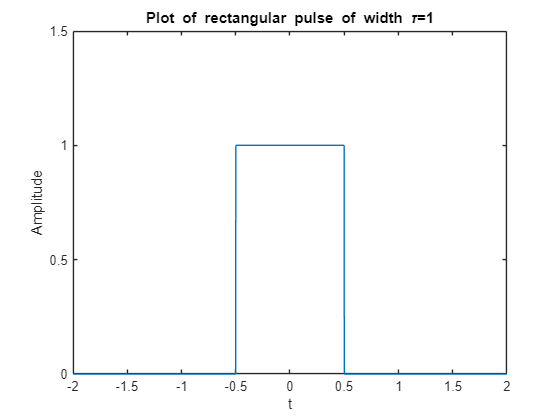

y=heaviside(t+0.5)-heaviside(t-0.5);

figure 
fplot(y)
title("Plot of rectangular pulse of width \tau=1")
xlabel("t")
ylabel("Amplitude");
ylim([0,1.5])
xlim([-2,2])

xlim([-2.00 2.00])
ylim([0.00 1.50])

Y=tau*sinc(pi*f*tau)

$$Y = \frac{\sin\left(f\,\pi^{2}\right)}{f\,\pi^{2}}$$

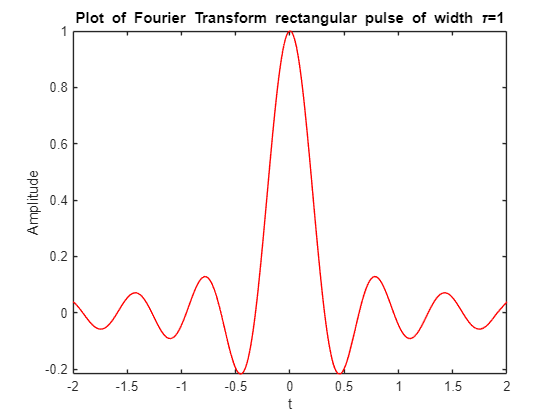

fplot(Y,color="red")
title("Plot of Fourier Transform rectangular pulse of width \tau=1")
xlabel("t")
ylabel("Amplitude");
%ylim([,1.5])
xlim([-2,2])

% Ideal lowpass filter of width of B=0.5/tau
function filter_plot(B,Y)
    syms f 
    figure 
    xlim([-B-0.5,B+0.5])
    LFP=heaviside(f+B)-heaviside(f-B);
    Filtered_signal=LFP*Y;
    subplot(1,3,1)
    fplot(Y);
    subplot(1,3,2)
    fplot(LFP)
    subplot(1,3,3)
    fplot(Filtered_signal)
    
end

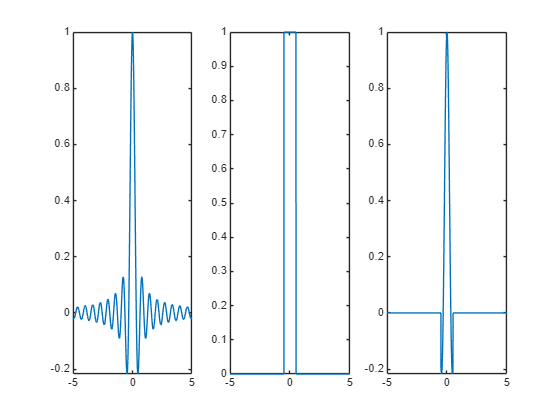

filter_plot(0.5,Y)